# **DSP Project Phase I**

**Ashkan Yousefnia                                                                                                                                                                                                                                           **

## Main Code

recObj = audiorecorder(16000,16,1);

recDuration = 3;
disp("Begin speaking.")

Begin speaking.


recordblocking(recObj,recDuration);
disp("End of recording.")

End of recording.




play(recObj);
signal = getaudiodata(recObj);
soundsc(signal,16000)

 
win = hamming(1024,"periodic");
%win = ones(1024,1)
NFFT = 1024;
ovlp = 75;


y1 = phaseVocoder(signal, NFFT, ovlp, win, 1); 
y2 = phaseVocoder(signal, NFFT, ovlp, win, 2); 
y3 = phaseVocoder(signal, NFFT, ovlp, win, 0.5); 


fprintf('Playing the reconstructed signal with alpha = 1 ...\n');

Playing the reconstructed signal with alpha = 1 ...


soundsc(y1,16000)
pause(3.2);
fprintf('Playing the reconstructed signal with alpha = 0.5 ...\n');

Playing the reconstructed signal with alpha = 0.5 ...


soundsc(y3,16000)
pause(3);
fprintf('Playing the reconstructed signal with alpha = 2 ...\n');

Playing the reconstructed signal with alpha = 2 ...


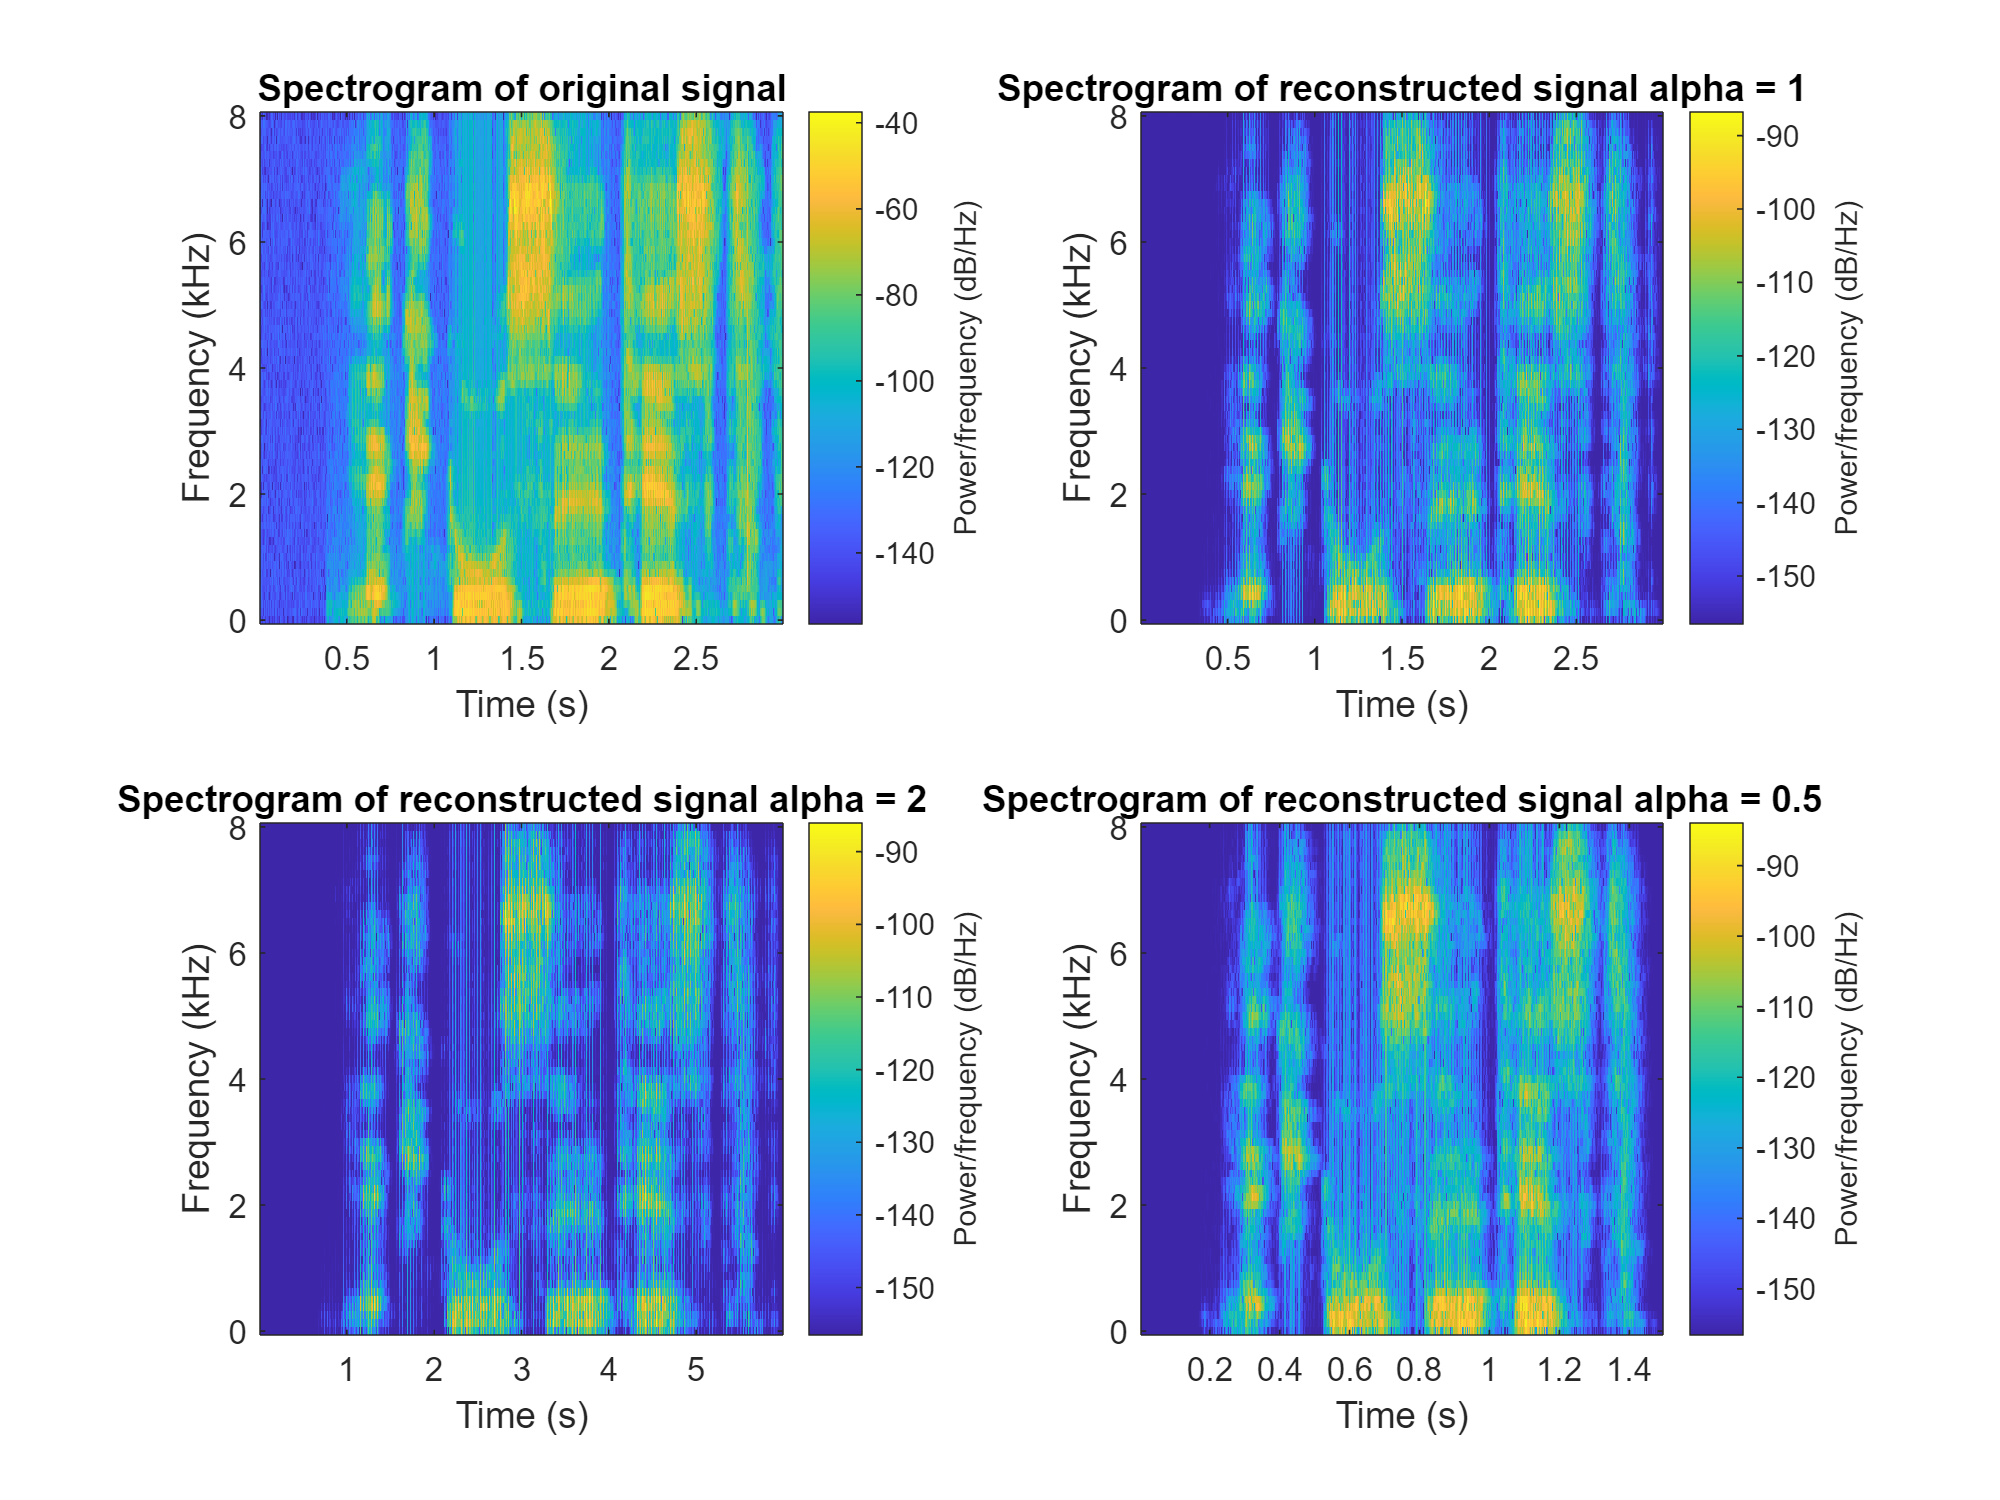

soundsc(y2,16000)

%% 
figure('Position', [100 100 800 600]);
subplot(2,2,1);
spectrogram(signal, 128, 120, 128, 16000, 'yaxis');
title(['Spectrogram of original signal']);
colormap parula;

subplot(2,2,2);
spectrogram(y1, 128, 120, 128, 16000, 'yaxis');
title(['Spectrogram of reconstructed signal alpha = 1']);


subplot(2,2,3);
spectrogram(y2, 128, 120, 128, 16000, 'yaxis');
title(['Spectrogram of reconstructed signal alpha = 2']);


subplot(2,2,4);
spectrogram(y3, 128, 120, 128, 16000, 'yaxis');
title(['Spectrogram of reconstructed signal alpha = 0.5']);


path1 = 'phase_one_voices\alpha1.wav';
path2 = 'phase_one_voices\alpha2.wav';
path3 = 'phase_one_voices\alpha0.5.wav';
y1_norm=y1/max(abs(y1))

y1_norm =          0
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000


y2_norm=y2/max(abs(y2))

y2_norm =          0
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000


y3_norm=y3/max(abs(y3))

y3_norm =          0
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000



audiowrite(path1, y1_norm, fs);
audiowrite(path2, y2_norm, fs);
audiowrite(path3, y3_norm, fs);

## Phase Vocoder Algorithm

function y = phaseVocoder(x, Nfft, ovlp, win, alpha)

    X = calcSTFT(x, Nfft, ovlp, win);
    Xmag = abs(X);
    Xph = angle(X);

    winLen = length(win);
    sigLen = length(x);
    hop = (1 - ovlp/100) * winLen;
    nFrames = 1 + ceil((sigLen - winLen)/hop);
    synHop = alpha * hop;

    dph = diff(Xph, 1, 2);
    binFreqs = 2 * pi * (0:Nfft-1)' / Nfft;
    expected = binFreqs * hop;
    delta = unwrap(dph - expected, pi, 2);
    trueFreqs = expected + delta;

    Yph = zeros(size(Xph));
    Yph(:,1) = Xph(:,1);
    for i = 2:nFrames-1
        Yph(:,i) = Yph(:,i-1) + (synHop/2)*(trueFreqs(:,i-1) + trueFreqs(:,i));
    end
    Yph(:,nFrames) = Yph(:,nFrames-1) + synHop * trueFreqs(:,nFrames-1);

    Y = Xmag .* exp(1j * Yph);

    nHops = ceil(winLen / synHop);
    bufLen = winLen + nHops * round(synHop);
    denomBuf = zeros(bufLen, 1);
    for n = 0:nHops
        idx1 = n * round(synHop) + 1;
        idx2 = idx1 + winLen - 1;
        if idx2 <= bufLen
            denomBuf(idx1:idx2) = denomBuf(idx1:idx2) + win.^2;
        end
    end
    winCorr = denomBuf(1:winLen);
    winSyn = (1/Nfft) * win ./ winCorr;

    y = zeros(round(sigLen*alpha), 1);
    for i = 1:nFrames
        frame = real(ifft(Y(:,i), Nfft));
        wFrame = frame .* winSyn;
        pos1 = round((i-1)*synHop) + 1;
        pos2 = pos1 + winLen - 1;
        if pos2 <= length(y)
            y(pos1:pos2) = y(pos1:pos2) + wFrame;
        end
    end
end

## Calculating Short-Time Fourier Transform

function out = calcSTFT(x, Nfft, overlap, window)
winLen = length(window);
sigLen = length(x);
hop = (1 - overlap/100) * winLen;
nFrames = ceil((sigLen - winLen) / hop) + 1;

out = zeros(winLen, nFrames);
for k = 1:nFrames
    idx_start = round((k-1)*hop) + 1;
    idx_end = idx_start + winLen - 1;
    if idx_end > sigLen
        segment = x(idx_start:end) .* window(1:(sigLen - idx_start + 1));
    else
        segment = x(idx_start:idx_end) .* window;
    end
    out(:,k) = fft(segment, Nfft);
end
end

# Questions

## question 1

The classical phase vocoder introduces artifacts like phasiness, transient smearing, and harmonic distortion because it processes each frequency bin independently while assuming stationary sinusoids. In reality, speech contains rapidly evolving harmonics and sharp transients that get misaligned. The fixed window size smears quick attacks like plosives ("p", "t"), blurring their clarity. Additionally, the phase vocoder breaks the natural harmonic structure by interpolating phases without preserving integer-multiple relationships between partials, leading to inharmonicity. Phase unwrapping errors further degrade quality when phase advances exceed ±π or bins contain multiple partials, causing random jumps. Since bins are processed separately, harmonic synchronization and transient alignment are lost, creating a synthetic, "robotized" sound. Modern solutions address these issues through transient detection, harmonic phase-locking, time-frequency reassignment, or machine learning to restore natural phase relationships. The core limitations stem from independent phase processing, rigid windowing, and lack of harmonic coherence preservation.

## question 2

done in the phase vocoder algorithm code part

## question 3

done in the main code part

## question 4

The original signal’s spectrogram shows well-defined harmonics and temporal structures, especially in the mid-frequency range between 1–4 kHz. When alpha = 1, the reconstructed signal preserves much of the original time-frequency pattern but exhibits slight smearing and reduced intensity, likely due to imperfect phase reconstruction. With alpha = 2, which slows down the signal, the temporal patterns stretch horizontally as expected, but this also introduces visible spectral smearing and blurred harmonic structures, indicating greater distortion. Conversely, when alpha = 0.5, the signal is compressed in time and the spectrogram becomes denser along the time axis. Interestingly, the harmonic structures and energy bands appear more intact and compact, suggesting less distortion, supporting the observation that time-compression is less prone to artifacts than time-stretching in phase vocoder implementations.

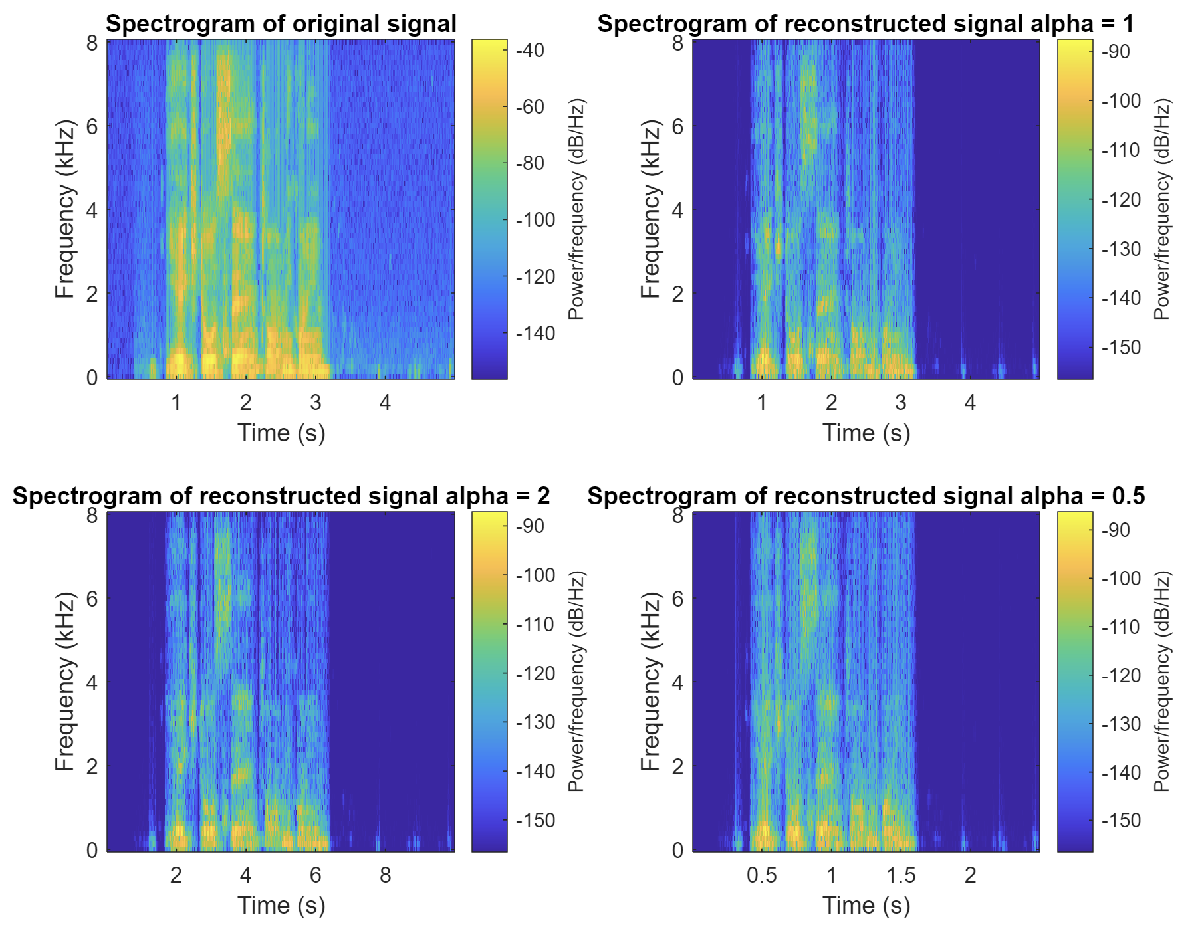

## question 5

the fastet voice with the smallest alpha is the less distorted one and the reconstructed signal with alpha=1 in the most distorted one.

In practice, faster playback (alpha < 1) often results in less perceptual distortion than slower playback (alpha > 1) because it reduces the chance of introducing phase and time-smearing artifacts. When stretching (alpha > 1), the algorithm must interpolate more between frames, requiring a more accurate estimation of the evolving phase, which is highly sensitive to windowing, FFT resolution, and analysis/synthesis hop mismatch. This often leads to audible phasiness or artificial resonances. In contrast, compressing the signal (alpha < 1) involves discarding frames, which tends to be less complex and less error-prone in terms of phase reconstruction, preserving the audio's natural quality more effectively.